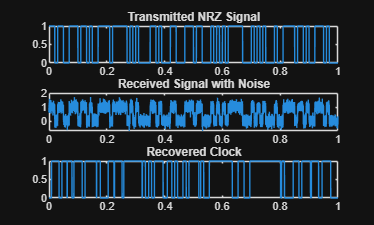

clc;
clear;
close all;

% PARAMETERS
fs = 10000;          % Sampling frequency
Rb = 100;            % Bit rate
Tb = 1/Rb;
samples_per_bit = fs/Rb;

Nbits = 100;

% Generate random data
data = randi([0 1],1,Nbits);

% NRZ Encoding
nrz = repelem(data,samples_per_bit);

% Add noise
rx_signal = nrz + 0.2*randn(size(nrz));

% Edge detection
edges = diff(rx_signal > 0.5);

% Simple clock recovery using transitions
clock = zeros(size(nrz));
clock(find(edges)) = 1;

% Generate periodic clock
clock = conv(clock,ones(1,samples_per_bit),'same');
clock = clock > 0;

% Plot results
t = (0:length(nrz)-1)/fs;

figure
subplot(3,1,1)
plot(t,nrz)
title('Transmitted NRZ Signal')

subplot(3,1,2)
plot(t,rx_signal)
title('Received Signal with Noise')

subplot(3,1,3)
plot(t,clock)
title('Recovered Clock')